# Stock Data - Importing Stock Information 

This file, `'StockInfo_SmallCap.xlsx'` contains 3 sheets:

-       Restaurants

-       ShippingServices

-       Oil_Gas_Drilling_Exploration

Each sheet contains 4 columns of data for various stocks:

-   TickerSymbol

-   StockName

-   StockSector

-   MarketCap

## 1. 

Import the data from the three sheets in the file `StockInfo_SmallCap.xlsx` into three tables. Concatenate these into a single table.

SmallCapStockInfo1 = readtable('StockInfo_SmallCap.xlsx','Sheet',1);
SmallCapStockInfo2 = readtable('StockInfo_SmallCap.xlsx','Sheet',2);
SmallCapStockInfo3 = readtable('StockInfo_SmallCap.xlsx','Sheet',3);

% Concatenate into a single table
SmallCapStockInfo = [SmallCapStockInfo1; SmallCapStockInfo2; SmallCapStockInfo3]

SmallCapStockInfo = 137×4 table
    TickerSymbol                StockName                 StockSector     MarketCap
    ____________    _________________________________    _____________    _________
    'AW-UN.TO'      'A&W REVENUE ROYALTIES INCOME FU'    'Restaurants'    '172.35M'
    'AFCE'          'AFC Enterprises, Inc.'              'Restaurants'    '387.22M'
    'BPF-UN.TO'     'BOSTON PIZZA ROYALTIES INCOME F'    'Restaurants'    '205.74M'
    'BNHNA'         'Benihana Inc.'                      'Restaurants'    '136.92M'
    'BH'            'Biglari Holdings Inc.'              'Restaurants'    '626.97M'
    'BOBE'          'Bob Evans Farms, Inc.'              'Restaurants'    '950.35M'
    'BBRG'          'Bravo Brio Restaurant Group, In'    'Restaurants'    '397.33M'
    'CEC'           'CEC Entertainment, Inc. Common'     'Restaurants'    '7

## 2. 

Clean up the market cap data by converting all data from text to numeric format. For example, text of the format ‘172.35M’ would be converted to a numeric value 172.35. To do this, use the `strrep `and `str2double `functions.

SmallCapStockInfo.MarketCap = strrep(SmallCapStockInfo.MarketCap, 'M', '');
% Convert to numeric data
SmallCapStockInfo.MarketCap = str2double(SmallCapStockInfo.MarketCap)

SmallCapStockInfo = 137×4 table
    TickerSymbol                StockName                 StockSector     MarketCap
    ____________    _________________________________    _____________    _________
    'AW-UN.TO'      'A&W REVENUE ROYALTIES INCOME FU'    'Restaurants'     172.35  
    'AFCE'          'AFC Enterprises, Inc.'              'Restaurants'     387.22  
    'BPF-UN.TO'     'BOSTON PIZZA ROYALTIES INCOME F'    'Restaurants'     205.74  
    'BNHNA'         'Benihana Inc.'                      'Restaurants'     136.92  
    'BH'            'Biglari Holdings Inc.'              'Restaurants'     626.97  
    'BOBE'          'Bob Evans Farms, Inc.'              'Restaurants'     950.35  
    'BBRG'          'Bravo Brio Restaurant Group, In'    'Restaurants'     397.33  
    'CEC'           'CEC Entertainment, Inc. Common'     'Restaurants'     7

## 3.

Convert the `StockSector` variable in the table to a categorical array.

SmallCapStockInfo.StockSector = categorical(SmallCapStockInfo.StockSector)

SmallCapStockInfo = 137×4 table
    TickerSymbol                StockName                StockSector    MarketCap
    ____________    _________________________________    ___________    _________
    'AW-UN.TO'      'A&W REVENUE ROYALTIES INCOME FU'    Restaurants     172.35  
    'AFCE'          'AFC Enterprises, Inc.'              Restaurants     387.22  
    'BPF-UN.TO'     'BOSTON PIZZA ROYALTIES INCOME F'    Restaurants     205.74  
    'BNHNA'         'Benihana Inc.'                      Restaurants     136.92  
    'BH'            'Biglari Holdings Inc.'              Restaurants     626.97  
    'BOBE'          'Bob Evans Farms, Inc.'              Restaurants     950.35  
    'BBRG'          'Bravo Brio Restaurant Group, In'    Restaurants     397.33  
    'CEC'           'CEC Entertainment, Inc. Common'     Restaurants     768.91  
    'CPKI'  

## 4.

Display a histogram of the `MarketCap` of all small-cap stocks in the Oil & Gas Drilling & Exploration sector. Bin the data into 10 bins.

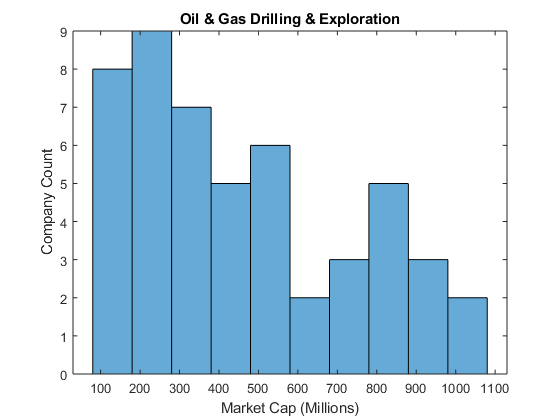

drillingSector = SmallCapStockInfo.StockSector == 'Oil & Gas Drilling & Exploration';

histogram(SmallCapStockInfo.MarketCap(drillingSector),10)
title('Oil & Gas Drilling & Exploration')
xlabel('Market Cap (Millions)')
ylabel('Company Count')